# Practical work 2 - Insertion Loss curves 

Viktoriia Boichenko, EM WAVES, 2022190966	

Initial values in order to set the geometry of proble			 

clear;
t=0.1;
A1=6;
A2=6;
L1=2.0+(A1+A2)/10.0;
L2=7.0+abs(A1-A2)/10.0;
L3=1.0+A1/10.0;
H=1.5+A2/10.0; 
H2=2*H;
Hs=0.5;
A1=6;
A2=6;
freq=500+A1*10+A2;
alpha1=(0.002*freq+0.04*log10(freq)-(0.0008*freq)^2)/(2*sqrt(A1+10));
alpha2=(0.002*freq+0.04*log10(freq)-(0.0008*freq)^2)/(2*sqrt(A1+5));
alpha3=(0.002*freq+0.04*log10(freq)-(0.0008*freq)^2)/(2*sqrt(A1+1));

SPL_avg

frequencies_all=100:10:1000;
frequencies_third=[125 160 200 250 315 400 500 630 800 1000 ];
frequencies_one=[125 250 500 1000];

SPL_avg_all=zeros(numel(frequencies_all),1);
SPL_avg_third=zeros(numel(frequencies_third),1);
SPL_avg_one=zeros(numel(frequencies_one),1);

SPL_avg_all_r=zeros(numel(frequencies_all),1);
SPL_avg_third_r=zeros(numel(frequencies_third),1);
SPL_avg_one_r=zeros(numel(frequencies_one),1);

All frequencies calculated SPL_avg

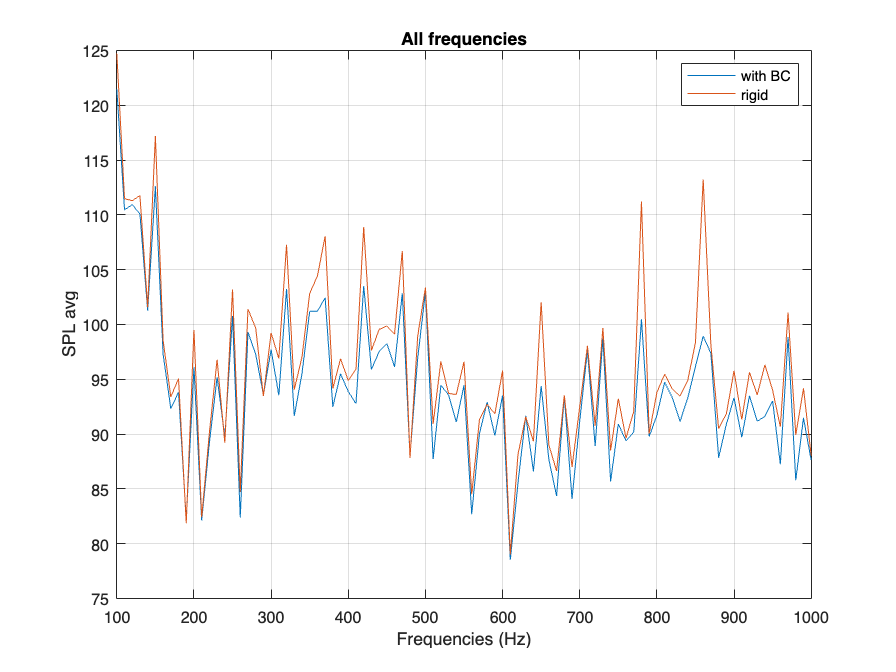

for ii=1:numel(frequencies_all)
    filename=strcat('results_f_',num2str(frequencies_all(ii)),'.mat');
    load(filename);
    n=find(x>1.5 & x<2 & y>0.5 & y<1.0);
    avgP2=sum(abs(P(n).^2))/numel(n);
    SPL_avg_all(ii)=10*log10(avgP2/(2e-5)^2);
end
for ii=1:numel(frequencies_all)
    filename=strcat('rigid-case/results_f_',num2str(frequencies_all(ii)),'.mat');
    load(filename);
    n=find(x>1.5 & x<2 & y>0.5 & y<1.0);
    avgP2=sum(abs(P(n).^2))/numel(n);
    SPL_avg_all_r(ii)=10*log10(avgP2/(2e-5)^2);
end
spl11 = plot(frequencies_all,SPL_avg_all);
hold on;
spl12 = plot(frequencies_all,SPL_avg_all_r);
hold off;
grid on;xlabel('Frequencies (Hz)');ylabel('SPL avg');
title('All frequencies');
legend([spl11, spl12] ,{'with BC','rigid'});

1/3 octave band frequencies calculated SPL_avg 

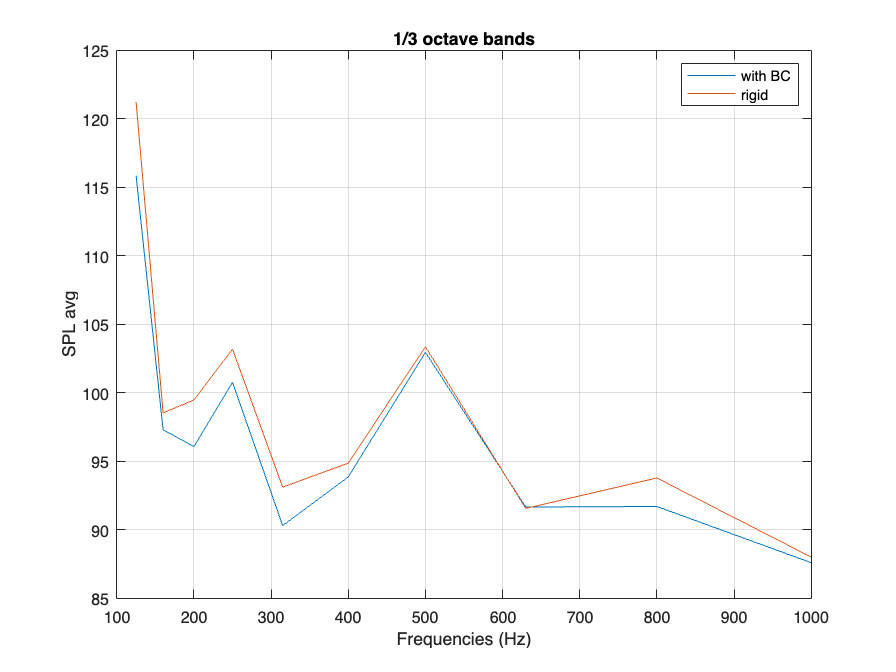

for ii=1:numel(frequencies_third)
    filename=strcat('results_f_',num2str(frequencies_third(ii)),'.mat');
    load(filename);
    n=find(x>1.5 & x<2 & y>0.5 & y<1.0);
    avgP2=sum(abs(P(n).^2))/numel(n);
    SPL_avg_third(ii)=10*log10(avgP2/(2e-5)^2);
end

for ii=1:numel(frequencies_third)
    filename=strcat('rigid-case/results_f_',num2str(frequencies_third(ii)),'.mat');
    load(filename);
    n=find(x>1.5 & x<2 & y>0.5 & y<1.0);
    avgP2=sum(abs(P(n).^2))/numel(n);
    SPL_avg_third_r(ii)=10*log10(avgP2/(2e-5)^2);
end


spl21 = plot(frequencies_third,SPL_avg_third);
hold on;
spl22 = plot(frequencies_third,SPL_avg_third_r);
hold off;
grid on;xlabel('Frequencies (Hz)');ylabel('SPL avg');
title('1/3 octave bands');
legend([spl21, spl22] ,{'with BC','rigid'});

1 octave band  frequencies calculated SPL_avg 

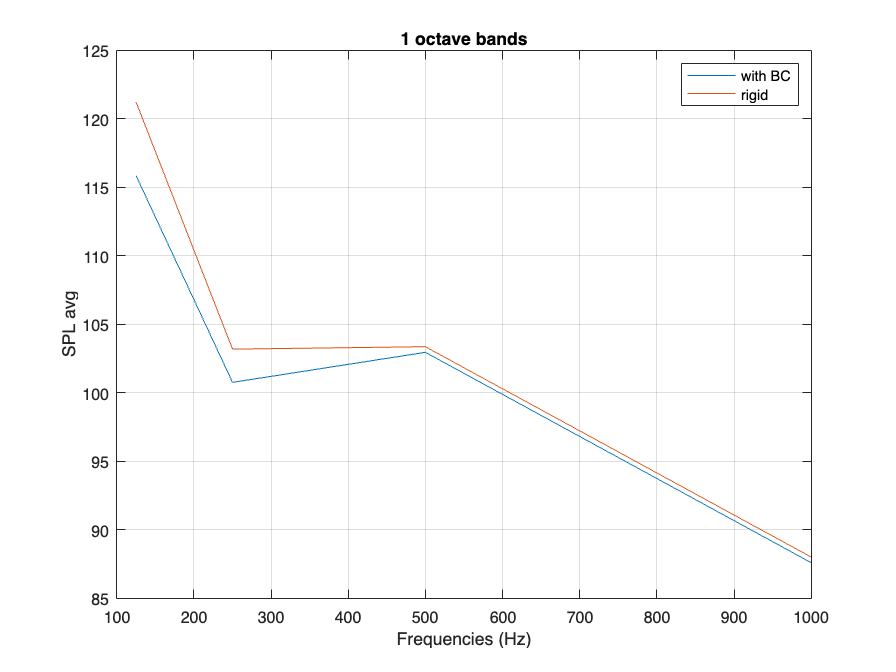

for ii=1:numel(frequencies_one)
    filename=strcat('results_f_',num2str(frequencies_one(ii)),'.mat');
    load(filename);
    n=find(x>1.5 & x<2 & y>0.5 & y<1.0);
    avgP2=sum(abs(P(n).^2))/numel(n);
    SPL_avg_one(ii)=10*log10(avgP2/(2e-5)^2);
end

for ii=1:numel(frequencies_one)
    filename=strcat('rigid-case/results_f_',num2str(frequencies_one(ii)),'.mat');
    load(filename);
    n=find(x>1.5 & x<2 & y>0.5 & y<1.0);
    avgP2=sum(abs(P(n).^2))/numel(n);
    SPL_avg_one_r(ii)=10*log10(avgP2/(2e-5)^2);
end

spl31 = plot(frequencies_one,SPL_avg_one);
hold on;
spl32 = plot(frequencies_one,SPL_avg_one_r);
hold off;
grid on;xlabel('Frequencies (Hz)');ylabel('SPL avg');
title('1 octave bands');
legend([spl31, spl32] ,{'with BC','rigid'});